addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')

% Casts 
cast01 = readSBScnv( 'ar0701001_hyst.cnv' );
cast02 = readSBScnv( 'ar0701002_hyst.cnv');
cast03 = readSBScnv( 'ar0701003_hyst.cnv' );
cast04 = readSBScnv( 'ar0701004_hyst.cnv' );
cast05 = readSBScnv( 'ar0701005_hyst.cnv' );
cast06 = readSBScnv( 'ar0701006_hyst.cnv' );
cast07 = readSBScnv( 'ar0701007_hyst.cnv' );
cast08 = readSBScnv( 'ar0701008_hyst.cnv' );
cast09 = readSBScnv( 'ar0701009_hyst.cnv' );
cast10 = readSBScnv( 'ar0701010_hyst.cnv' );

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year3')
btl = readtable('Irminger_Sea-03_AR7-01_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum05 = btl(btl.Cast == 5,:);
btlsum06 = btl(btl.Cast == 6,:);
btlsum07 = btl(btl.Cast == 7,:);
btlsum08 = btl(btl.Cast == 8,:);
btlsum09 = btl(btl.Cast == 9,:);
btlsum10 = btl(btl.Cast == 10,:);

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year3')

btl05 = readtable('ar0701005_hyst.csv','TextType','string');

btl06 = readtable('ar0701006_hyst.csv','TextType','string');

btl07 = readtable('ar0701007_hyst.csv','TextType','string');

btl08 = readtable('ar0701008_hyst.csv','TextType','string');

btl09 = readtable('ar0701009_hyst.csv','TextType','string');

btl10 = readtable('ar0701010_hyst.csv','TextType','string');


% Join tables 
btlsum05 = join(btl05,btlsum05,'Keys',"Bottle");
btlsum06 = join(btl06,btlsum06,'Keys',"Bottle");
btlsum07 = join(btl07,btlsum07,'Keys',"Bottle");
btlsum08 = join(btl08,btlsum08,'Keys',"Bottle");
btlsum09 = join(btl09,btlsum09,'Keys',"Bottle");
btlsum10 = join(btl10,btlsum10,'Keys',"Bottle");

clear btl0* btl1* btl2*

% Same Oxygen Sensor for whole cruise 
% Calibration standards from SBE xmlcon file 

cal.SOC = double(3.79510e-001);
cal.VOFFSET = double(-5.82400e-001);
cal.A = double(-4.14790e-003);
cal.B = double(2.08070e-004);
cal.C = double(-3.05950e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.16000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '0338';
cal.OCALDATE = '16-Jan-16';

H = [-0.033, 5000, 1450]; % Default 

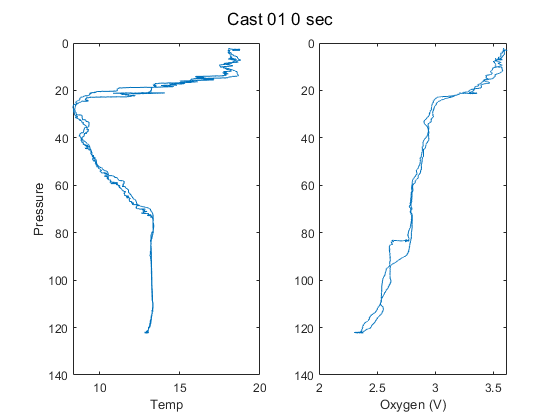

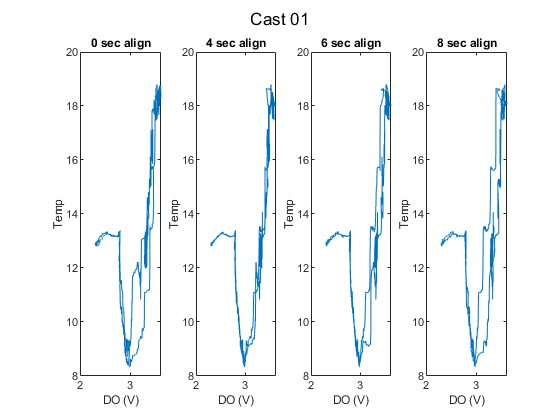

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 4; a2 = 6; a3 = 8;

cast01 = align_CTD_KF(cast01,'Cast 01',a1,a2,a3);

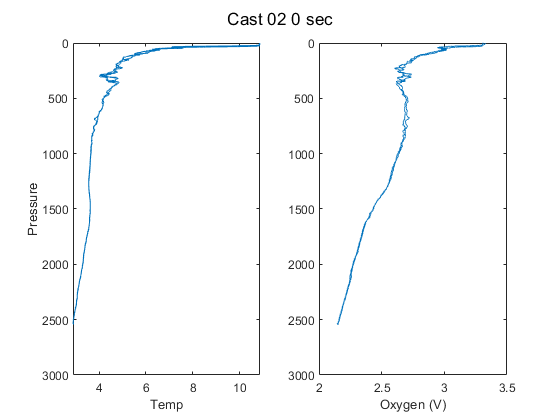

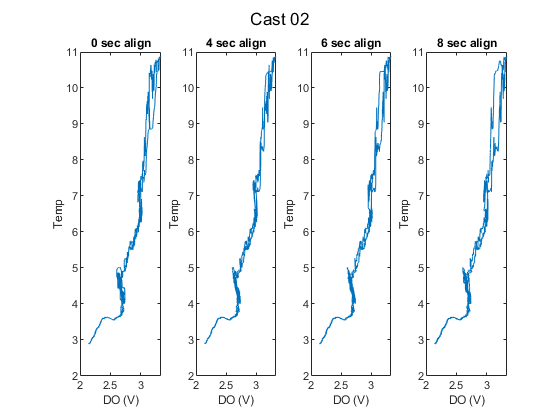

cast02 = align_CTD_KF(cast02,'Cast 02',a1,a2,a3);

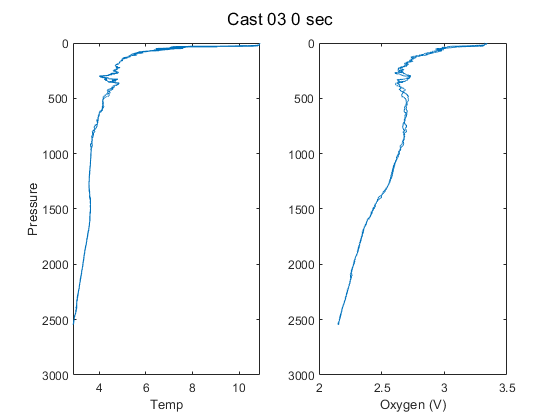

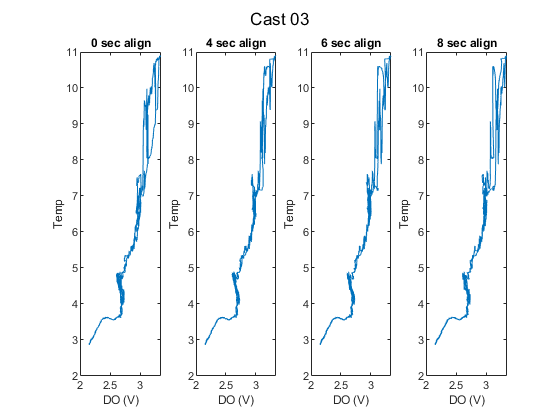

cast03 = align_CTD_KF(cast03,'Cast 03',a1,a2,a3);

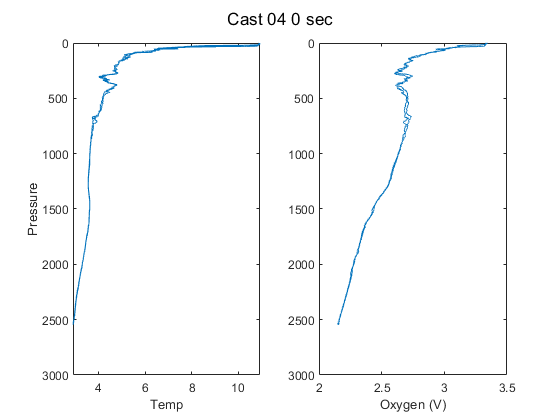

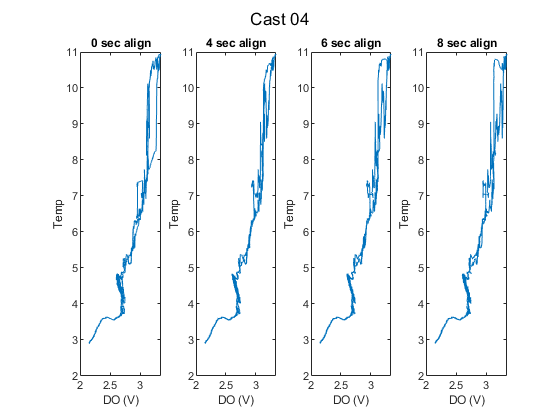

cast04 = align_CTD_KF(cast04,'Cast 04',a1,a2,a3);

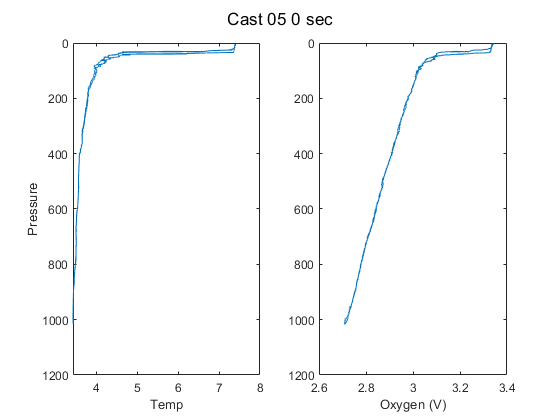

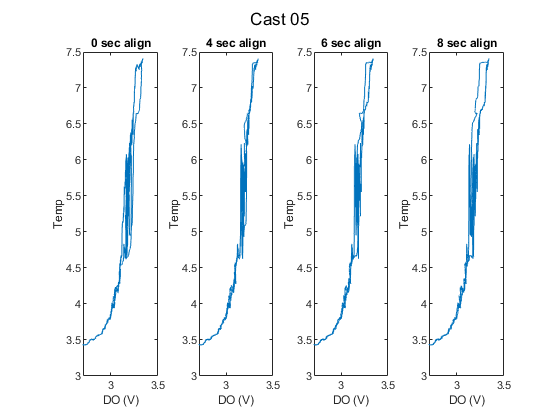

cast05 = align_CTD_KF(cast05,'Cast 05',a1,a2,a3);

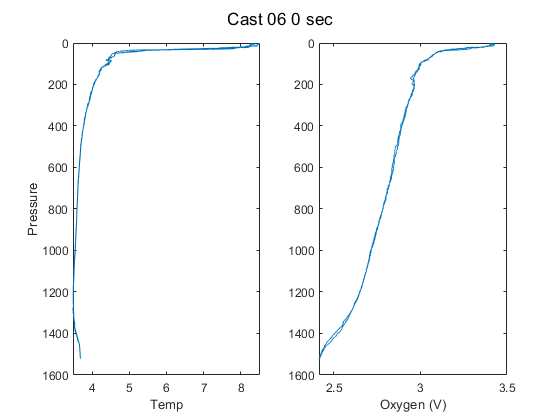

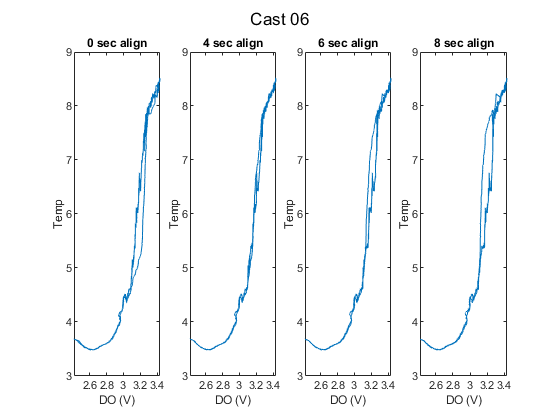

cast06 = align_CTD_KF(cast06,'Cast 06',a1,a2,a3);

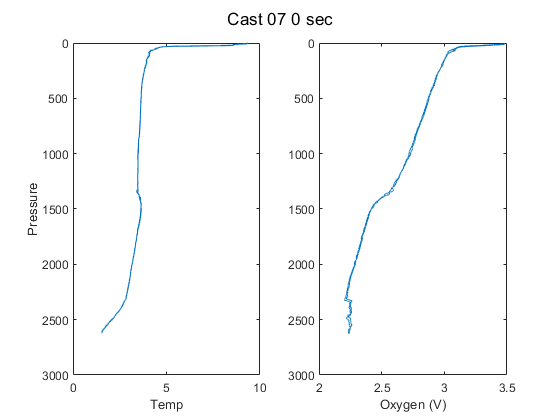

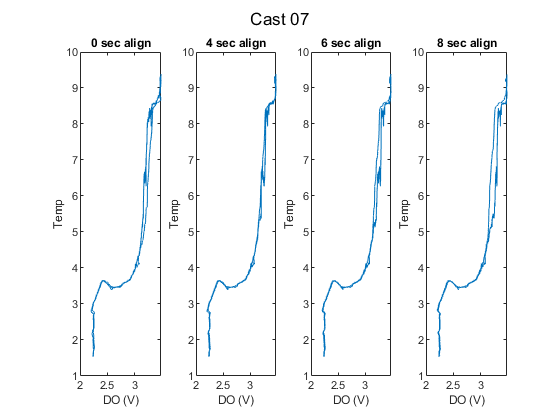

cast07 = align_CTD_KF(cast07,'Cast 07',a1,a2,a3);

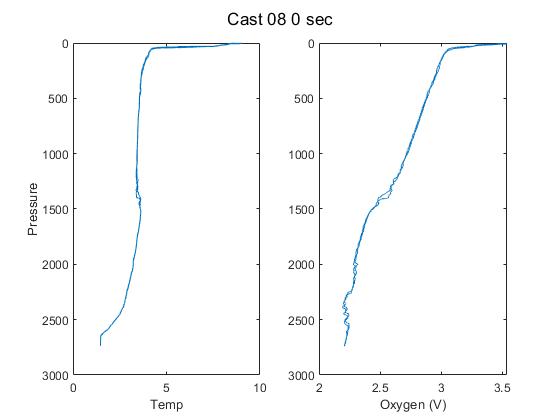

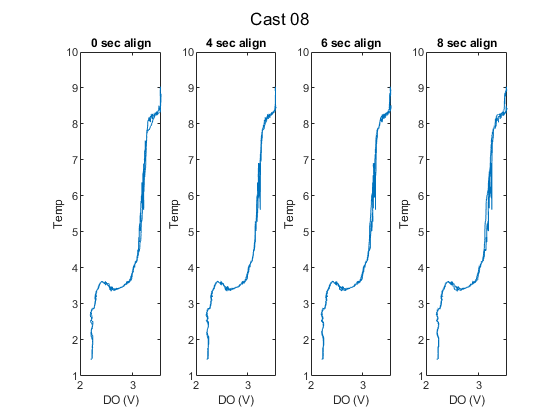

cast08 = align_CTD_KF(cast08,'Cast 08',a1,a2,a3);

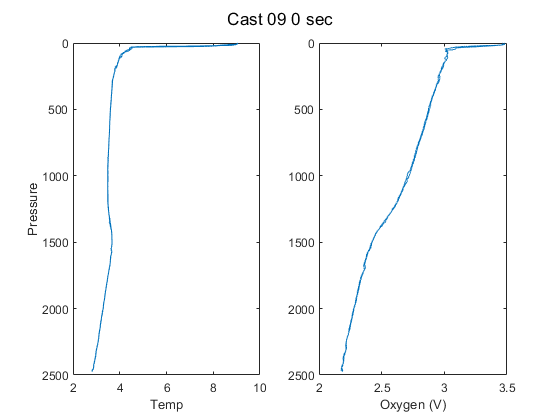

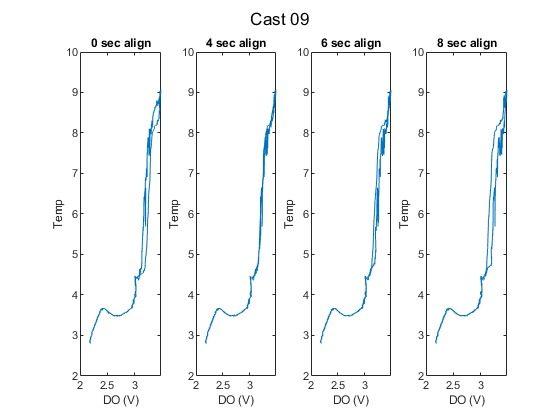

cast09 = align_CTD_KF(cast09,'Cast 09',a1,a2,a3);

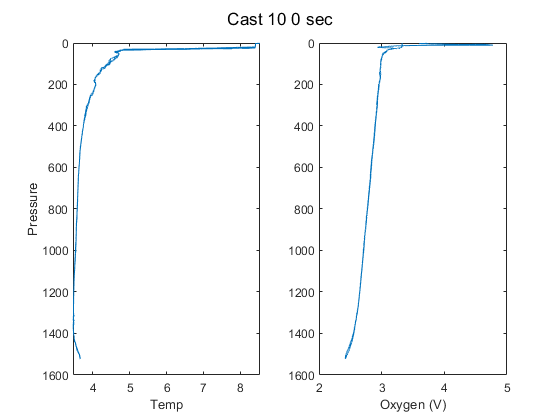

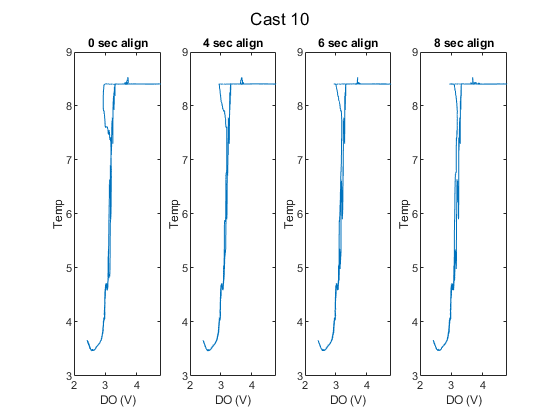

cast10 = align_CTD_KF(cast10,'Cast 10',a1,a2,a3);


% Pick align_sec

align_sec = a1; 

cast01.DOv = SBE_alignCTDW(cast01.sbeox0V, align_sec, 1/24 );
cast02.DOv = SBE_alignCTDW(cast02.sbeox0V, align_sec, 1/24 );
cast03.DOv = SBE_alignCTDW(cast03.sbeox0V, align_sec, 1/24 );
cast04.DOv = SBE_alignCTDW(cast04.sbeox0V, align_sec, 1/24 );
cast05.DOv = SBE_alignCTDW(cast05.sbeox0V, align_sec, 1/24 );
cast06.DOv = SBE_alignCTDW(cast06.sbeox0V, align_sec, 1/24 );
cast07.DOv = SBE_alignCTDW(cast07.sbeox0V, align_sec, 1/24 );
cast08.DOv = SBE_alignCTDW(cast08.sbeox0V, align_sec, 1/24 );
cast09.DOv = SBE_alignCTDW(cast09.sbeox0V, align_sec, 1/24 );
cast10.DOv = SBE_alignCTDW(cast10.sbeox0V, align_sec, 1/24 );


% H = [-0.02, 5000, 1850];
% align = 1; 
% [cast03] = adjust_hysteresis_KF(cast03,'Cast 03',H,cal,align);
% [cast04] = adjust_hysteresis_KF(cast04,'Cast 04',H,cal,align);
% [cast05] = adjust_hysteresis_KF(cast05,'Cast 05',H,cal,align);

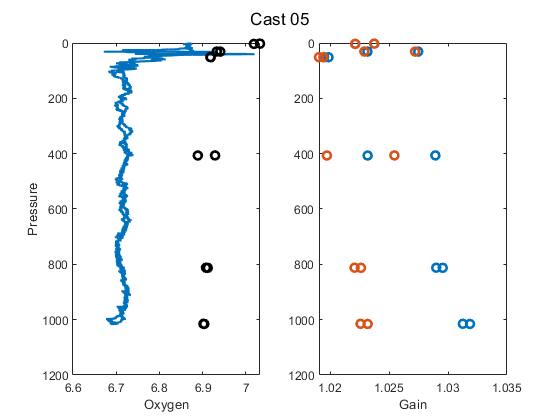

Gain = 1.0258+/- 0.0043655
EGain = 1.0225+/- 0.0023802


E = cal.E;
E2 = 3.83e-2;


btlsum05 = CTD_Gain_KF(btlsum05,cast05,'Cast 05',E,E2);

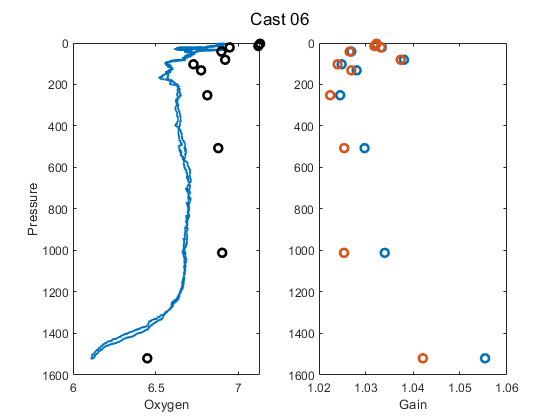

Gain = 1.0326+/- 0.0085931
EGain = 1.0297+/- 0.0061478


btlsum06 = CTD_Gain_KF(btlsum06,cast06,'Cast 06',E,E2);

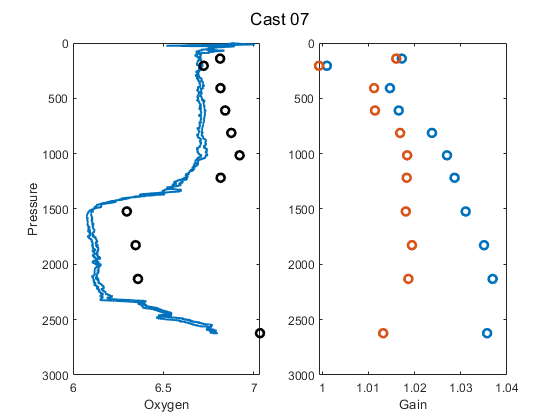

Gain = 1.0243+/- 0.01105
EGain = 1.0146+/- 0.0058673


btlsum07 = CTD_Gain_KF(btlsum07,cast07,'Cast 07',E,E2);

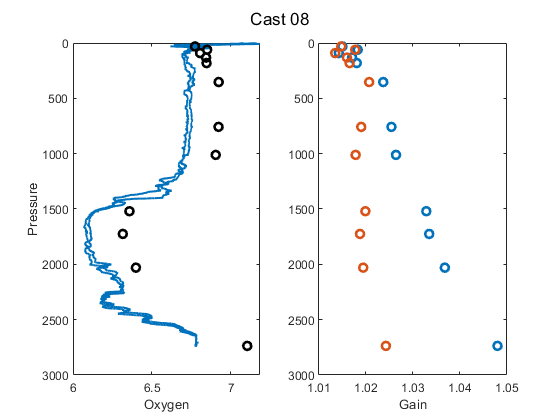

Gain = 1.0258+/- 0.010317
EGain = 1.0182+/- 0.0028708


btlsum08 = CTD_Gain_KF(btlsum08,cast08,'Cast 08',E,E2);

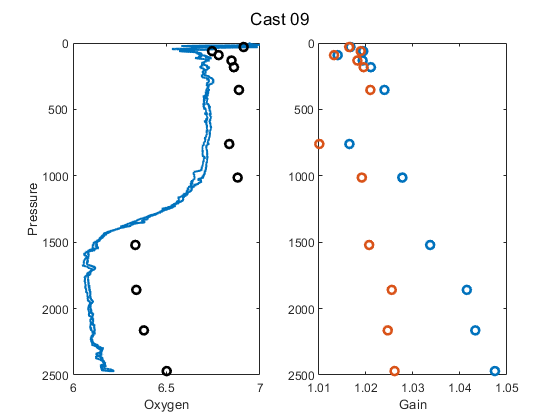

Gain = 1.027+/- 0.011615
EGain = 1.0194+/- 0.0047576


btlsum09 = CTD_Gain_KF(btlsum09,cast09,'Cast 09',E,E2);

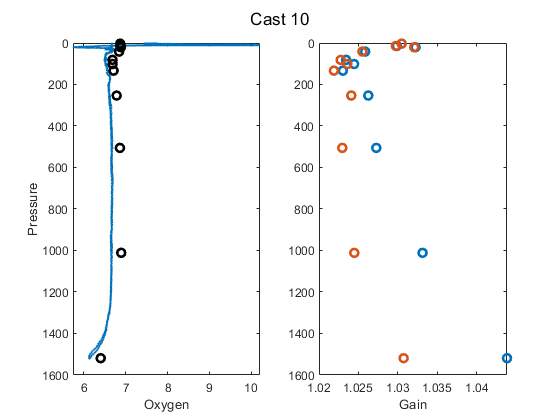

Gain = 1.0291+/- 0.0059812
EGain = 1.0262+/- 0.0037589


btlsum10 = CTD_Gain_KF(btlsum10,cast10,'Cast 10',E,E2);

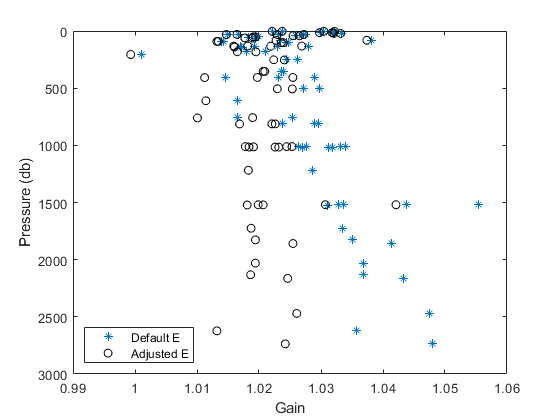


btlsum = [btlsum05; btlsum06; btlsum07; btlsum08; btlsum09; btlsum10];

depth_cut = 500;

figure
plot(btlsum.gain,btlsum.PrDM,'*')
hold on
plot(btlsum.Egain,btlsum.PrDM,'ok')
% plot(btlsum.Egain(btlsum.PrDM > depth_cut),btlsum.PrDM(btlsum.PrDM > depth_cut),'ok')
axis ij
ylabel('Pressure (db)')
xlabel('Gain')
legend('Default E','Adjusted E','Location','SW')


disp(['Gain = ' num2str(nanmean(btlsum.gain(btlsum.PrDM > depth_cut))) '+/- ' num2str(nanstd(btlsum.gain(btlsum.PrDM > depth_cut)))])

Gain = 1.0331+/- 0.0086292


disp(['EGain = ' num2str(nanmean(btlsum.Egain(btlsum.PrDM > depth_cut))) '+/- ' num2str(nanstd(btlsum.Egain(btlsum.PrDM > depth_cut)))])

EGain = 1.0214+/- 0.0059208


cal.SOCnew = cal.SOC*nanmean(btlsum.Egain(btlsum.PrDM > depth_cut));
disp(['DO align (s) = ' num2str(align_sec)])

DO align (s) = 4


disp(['Cal. E term = ' num2str(cal.E)])

Cal. E term = 0.036


disp(['Adjust. E term = ' num2str(E2)])

Adjust. E term = 0.0383


disp(['Cal SOC = ' num2str(cal.SOC)])

Cal SOC = 0.37951


disp(['New SOC = ' num2str(cal.SOCnew) ])

New SOC = 0.38762
